clc; clear; close all;

v = [16.5957 17.1731 15.7237 17.4929 19.6742];
f = 3000:500:5000;
k = 2*pi*f./v; 
h = 0.5747/2 * ones(size(v)) / 1000;

muestras = [1 2];
v = v(muestras);
f = f(muestras);
k = k(muestras);
h = h(muestras);

kh = k.*h;
% Valor inicial para fsolve
eta0 = 0.9;

% Opciones de fsolve
options = optimset('Display','off');

% Usamos arrayfun para aplicar fsolve a cada par (k(i), h(i))
eta_sol = arrayfun(@(khi) ...
    fsolve(@(eta) 4*eta.*tanh(eta*khi)./tanh(khi) - (1+eta.^2).^2, ...
           eta0, options), ...
    kh);

disp('Soluciones para eta:')

Soluciones para eta:


disp(eta_sol)

    0.9383    0.9241



rho = 1050;

x = eta_sol.^2

x =     0.8803    0.8540


y = rho*v.^2

y = 1.0e+05 *

    2.8919    3.0966


% Ajuste lineal (grado 1)
p = polyfit(x, y, 1);

% Pendiente y ordenada al origen
m = p(1);
b = p(2);

disp(['Recta ajustada: y = ' num2str(m) ' * x + ' num2str(b)])

Recta ajustada: y = -776076.3903 * x + 972393.0113


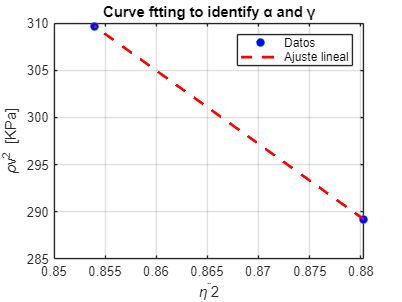


% Calcular valores ajustados
y_fit = polyval(p, x);

% Graficar
figure();
plot(x, y/1000, 'o', 'MarkerFaceColor', 'b'); hold on
plot(x, y_fit/1000, '--r', 'LineWidth', 2);
title('Curve ftting to identify α and γ')
legend('Datos', 'Ajuste lineal')
xlabel('\eta^¨2'); ylabel('\rhov^2 [KPa]');
grid on

% Resultados
alpha = b

alpha = 9.7239e+05

gamma = -m

gamma = 7.7608e+05


stress = alpha - gamma

stress = 1.9632e+05

strain = -1 + (alpha/gamma)^(1/3)

strain = 0.0781

young = stress/strain

young = 2.5147e+06